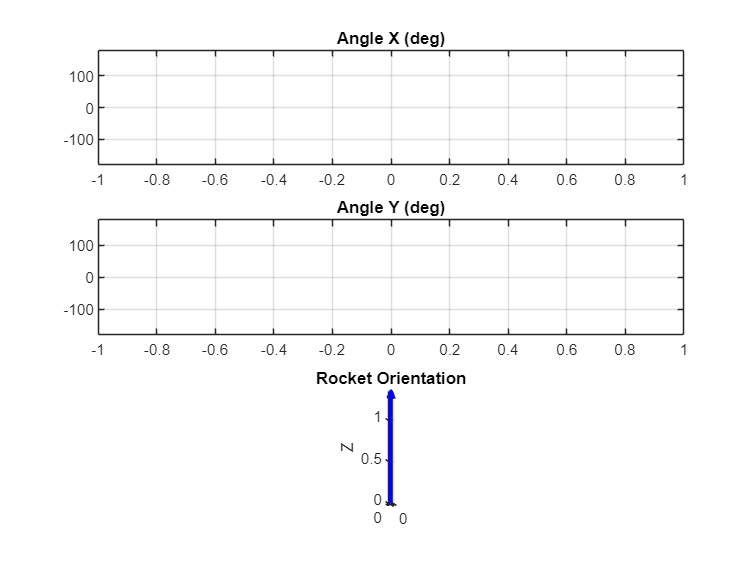

Reading data from Arduino...


% Define the serial port and baud rate

arduinoPort = "COM5"; % Replace with the correct COM port for your Arduino
baudRate = 115200;      % Must match the Arduino sketch

% Create the serial port object
arduino = serialport(arduinoPort, baudRate);

% Set the number of bytes to read (optional)
configureTerminator(arduino, "CR/LF"); % Match the newline terminator used in Arduino

% Initialize arrays with fixed lengths
numPoints = 1000;
time_arr = zeros(1, numPoints);
ang_x_arr = zeros(1, numPoints);
ang_y_arr = zeros(1, numPoints);
ang_z_arr = zeros(1, numPoints);
acc_x_arr = zeros(1, numPoints);
acc_y_arr = zeros(1, numPoints);
acc_z_arr = zeros(1, numPoints);

% Initialize figure and subplots
figure
subplot(3,1,1)
h1 = plot(0,0); % Create empty plot handle
ylim([-180 180])  % Set y-axis limits
title('Angle X (deg)')
grid on

subplot(3,1,2)
h2 = plot(0,0); % Create empty plot handle
ylim([-180 180])
title('Angle Y (deg)')
grid on

subplot(3,1,3)
h3 = plot(0,0); % Create empty plot handle
ylim([-180 180])
title('Angle Z (deg)')
grid on

% Read and display data
disp('Reading data from Arduino...');
while true
    % Read one line of data
    data = readline(arduino);
    data_arr = split(data, ',');
    
    try
        time = data_arr(1);
        ang_x = data_arr(2);
        ang_y = data_arr(3);
        ang_z = data_arr(4);
        acc_x = data_arr(5);
        acc_y = data_arr(6);
        acc_z = data_arr(7);
    
        % Update arrays by shifting and adding new values
        time_arr = [time_arr(2:end), str2double(time)];
        ang_x_arr = [ang_x_arr(2:end), str2double(ang_x)];
        ang_y_arr = [ang_y_arr(2:end), str2double(ang_y)];
        ang_z_arr = [ang_z_arr(2:end), str2double(ang_z)];
        acc_x_arr = [acc_x_arr(2:end), str2double(acc_x)];
        acc_y_arr = [acc_y_arr(2:end), str2double(acc_y)];
        acc_z_arr = [acc_z_arr(2:end), str2double(acc_z)];
    end
    
    % Time to plot
    set(h1, 'YData', ang_x_arr, 'XData', time_arr);
    set(h2, 'YData', ang_y_arr, 'XData', time_arr);
    set(h3, 'YData', ang_z_arr, 'XData', time_arr);

    drawnow

end
